# Init

clear
addpath 'Functions'
load('Functions\GAFdtdOptParm.mat','OptParm')
api_path = 'C:\Program Files\Lumerical\v202\api\matlab';
sim_file_path=('D:\CodeProject\DeflectorOptimize\Main'); 
sim_file_name=('DOE_Optimization.fsp');

% init FDTD engine
fdtd_handle = InitFdtd1D(api_path,sim_file_path,sim_file_name);

错误使用 appopen
Unable to launch the requested application

出错 InitFdtd1D (line 5)
h=appopen('fdtd');

# Optimization using genetic algorithm

if max(size(gcp)) == 0 % parallel pool needed
    parpool('local',12);
end


% 厚度
OptParm.Geometry.Thickness = 3100;



fig_handle = figure('Position',[0 0 300 150]);

fun = @(x) -FomFdtd1D(fdtd_handle,InPattern,OptParm,fig_handle)
nvars = length(OptParm.Geometry.PixelNum);
IntCon = 1:nvars;
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1,nvars);
ub = (OptParm.Geometry.Level-1)*ones(1,nvars);
nonlcon = [];
options = optimoptions('ga',...
    'UseParallel', true,...
    'PlotFcn','gaplotbestf',...
    'MaxTime',6000);

x_list = {};
RunTimes = 20;
for ii=1:RunTimes
    figure('Position',[0 0 250 150])
    x = ga(fun,nvars,A,b,Aeq,beq,lb,ub,nonlcon,IntCon,options);
    x_list = [x_list,x];
    drawnow
end
save("StructureGA_list.mat",'x_list')

# Simulation validation

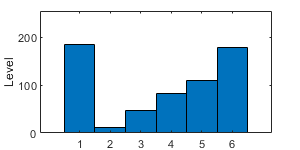

% 读取
load("StructureGA.mat",'x')
load('Functions\OptParm.mat','OptParm')
% 波长
wavelength_list = [1500,1550,1600];
% 无偏差
OptParm.Optimization.Robustness.StartDeviation = [0]; % Starting height deviation values
OptParm.Optimization.Robustness.Weights = [1];
% 遍历
FOM_list = zeros(length(wavelength_list),2);
for ii = 1:length(wavelength_list)
    OptParm.Input.Wavelength = wavelength_list(ii);
    OptParm.Input.Polarization = 'TM';
    FOM_list(ii,1) = FigureOfMerit1D(x,OptParm);
    OptParm.Input.Polarization = 'TE';
    FOM_list(ii,2) = FigureOfMerit1D(x,OptParm);
end
% 显示结构
figure('Position',[0 0 300 150])
bar(x,1)
ylabel('Level')
ylim([0 (OptParm.Geometry.Level-1)])

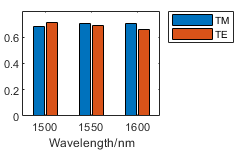


figure('Position',[0 0 250 150])
bar(wavelength_list,FOM_list);
xlabel('Wavelength/nm')
legend('TM','TE','Location','northeastoutside')

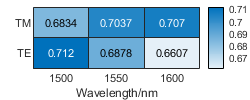


figure('Position',[0 0 250 100])
heatmap(wavelength_list,{'TM','TE'},FOM_list')
xlabel('Wavelength/nm')

# List Simulation validation

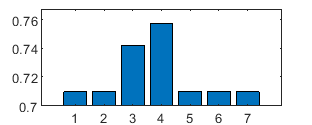

% 读取
load("StructureGA_list.mat",'x_list')
Eff_avg = zeros(1,length(x_list));
parfor ii=1:length(x_list)
    Eff_avg(ii) = FigureOfMerit1D(x_list{ii},OptParm);
end
figure('Position',[0 0 250 100])
bar(Eff_avg);
ylim([min(Eff_avg)-0.01,max(Eff_avg)+0.01])